# Homework 3

**Name:** YOUR NAME HERE

**Due Date: **

clear, clc, format compact
format long

## Problem #1 - Numerical integration methods 

**SETUP FOR PROBLEM**

fQ1 = @(x) 10.*x.^5+2.2.*x.^4-0.1.*x.^3-0.8.*x.^2-6;
a = 1;
b = 4;

**a) Exact integral**

syms x
ifQ1Exact = double(int(fQ1, x, a ,b))

ifQ1Exact =      7.233945000000000e+03

**b) Trapezoid - Single application**

integralTrapazoidalfQ1b = (b-a)/2*(fQ1(a)+fQ1(b))

integralTrapazoidalfQ1b =      1.617495000000000e+04

**c) Trapezoid Rule - Composite application (n=7)**

n = 7;
stepc = (b-a)/n;

itegralTrapazoidalfQ1c = stepc*(fQ1(a)/2+fQ1(a+stepc)+fQ1(a+2*stepc)+fQ1(a+3*stepc)+fQ1(a+4*stepc)+fQ1(a+5*stepc)+fQ1(a+6*stepc)+fQ1(b)/2)

itegralTrapazoidalfQ1c =      7.437012307371927e+03

**d) Simpson's 1/3 Rule - Single application**

n = 2;
stepd = (b-a)/n;

integralSimpson13fQ1d = stepd/3*(fQ1(a)+4*fQ1(a+stepd)+fQ1(b))

integralSimpson13fQ1d =      7.491525000000001e+03

**e) Simpson's 3/8 Rule - Single application**

n = 3;
stepe = (b-a)/n;

integralSimpson38fQ1e = (3*stepe)/8*(fQ1(a)+3*fQ1(a+stepe)+3*fQ1(a+2*stepe)+fQ1(b))

integralSimpson38fQ1e =      7.348425000000001e+03

**f) Hybrid Simpson's (n=7)**

[simp118,simp811,simp181] = simpsons7(fQ1,a,b)

simp118 =      7.236890850113473e+03

simp811 =      7.236271210337529e+03

simp181 =      7.236581030225500e+03

**g) Table with integral results**

fprintf('Method          Value      MTPRE\n--------------- ---------- --------\nExact           %10.4f%9.4f\nTrapSingle      %10.4f%9.4f\nSimpsons 1/3    %10.4f%9.4f\nSimpsons 3/8    %10.4f%9.4f\nTrapComposite   %10.4f%9.4f\nS13 - S13 - S38 %10.4f%9.4f\nS38 - S13 - S13 %10.4f%9.4f\nS13 - S38 - S13 %10.4f%9.4f',ifQ1Exact,mprte(ifQ1Exact,ifQ1Exact),integralTrapazoidalfQ1b,mprte(ifQ1Exact,integralTrapazoidalfQ1b),integralSimpson13fQ1d,mprte(ifQ1Exact,integralSimpson13fQ1d),integralSimpson38fQ1e,mprte(ifQ1Exact,integralSimpson38fQ1e),itegralTrapazoidalfQ1c,mprte(ifQ1Exact,itegralTrapazoidalfQ1c),simp118,mprte(ifQ1Exact,simp118),simp811,mprte(ifQ1Exact,simp811),simp181,mprte(ifQ1Exact,simp181))

Method          Value      MTPRE
--------------- ---------- --------
Exact            7233.9450   0.0000
TrapSingle      16174.9500 123.5979
Simpsons 1/3     7491.5250   3.5607
Simpsons 3/8     7348.4250   1.5825
TrapComposite    7437.0123   2.8071
S13 - S13 - S38  7236.8909   0.0407
S38 - S13 - S13  7236.2712   0.0322
S13 - S38 - S13  7236.5810   0.0364

## Problem #2 - Integrating real data

**SETUP FOR PROBLEM**

distanceInMeters = [0 .34 .99 1.6 2.27 2.96 3.52 3.95 4.54 5];
temperatureInFarinheight = [-6.29 -1.79 4.57 12.59 12.49 40.73 50.44 67.7 93.2 99.43];

**a) Plot the data**

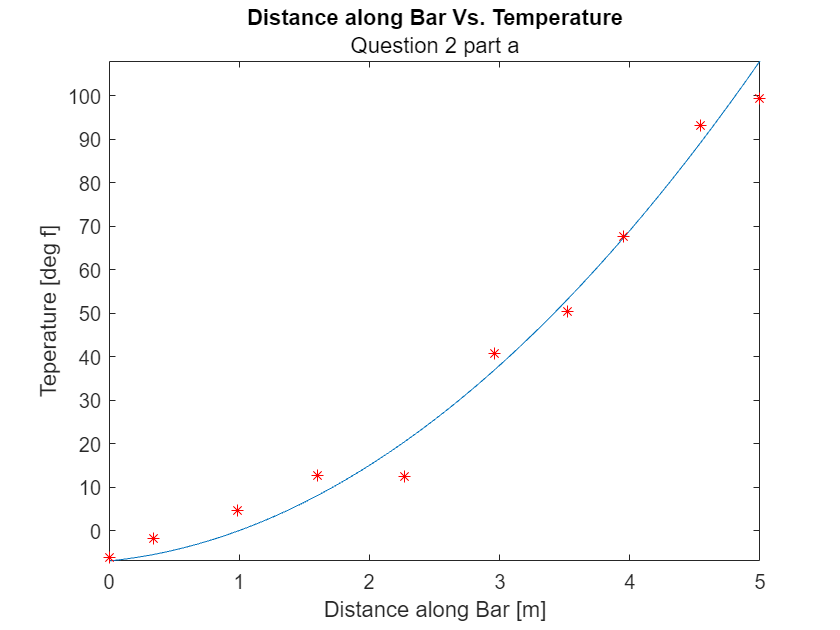

clf
estematedTempAlongBar = @(x) 4.*x.^2+3.*x-7;

fplot(estematedTempAlongBar,[0 5])
xlabel('Distance along Bar [m]')
ylabel('Teperature [deg f]')
title('Distance along Bar Vs. Temperature','Question 2 part a')
hold on;

for i = 1:10
    plot(distanceInMeters(i),temperatureInFarinheight(i),'r*')
end

**b) Estimate the integral of the data**

trapIt(1) = (distanceInMeters(2)-distanceInMeters(1))*((temperatureInFarinheight(2)+temperatureInFarinheight(1))/2);
trapIt(2) = (distanceInMeters(3)-distanceInMeters(2))*((temperatureInFarinheight(3)+temperatureInFarinheight(2))/2);
trapIt(3) = (distanceInMeters(4)-distanceInMeters(3))*((temperatureInFarinheight(4)+temperatureInFarinheight(3))/2);
trapIt(4) = (distanceInMeters(5)-distanceInMeters(4))*((temperatureInFarinheight(5)+temperatureInFarinheight(4))/2);
trapIt(5) = (distanceInMeters(6)-distanceInMeters(5))*((temperatureInFarinheight(6)+temperatureInFarinheight(5))/2);
trapIt(6) = (distanceInMeters(7)-distanceInMeters(6))*((temperatureInFarinheight(7)+temperatureInFarinheight(6))/2);
trapIt(7) = (distanceInMeters(8)-distanceInMeters(7))*((temperatureInFarinheight(8)+temperatureInFarinheight(7))/2);
trapIt(8) = (distanceInMeters(9)-distanceInMeters(8))*((temperatureInFarinheight(9)+temperatureInFarinheight(8))/2);
trapIt(9) = (distanceInMeters(10)-distanceInMeters(9))*((temperatureInFarinheight(10)+temperatureInFarinheight(9))/2);
iQ2Estemate = sum(trapIt);

fprintf('An estemate for the value of the integral is %.4f',iQ2Estemate)

An estemate for the value of the integral is 174.2245

**c) Magnitude true percent relative error**

syms x
theoreticalIntegral = int(estematedTempAlongBar,x,0,5);
fprintf('The MTPRE between the theoretical function and the mesured values is %.2f%%',mprte(theoreticalIntegral,iQ2Estemate))

The MTPRE between the theoretical function and the mesured values is 2.99%

## Problem #3 - 2D Integration

**SETUP FOR PROBLEM**

fQ3 = @(x,y) 133+ ((x.^5)/32768+(y.^5)/7776);
a = -12;
b = -6.7;
c = -10;
d = 4;

**a) 3D plot of function**

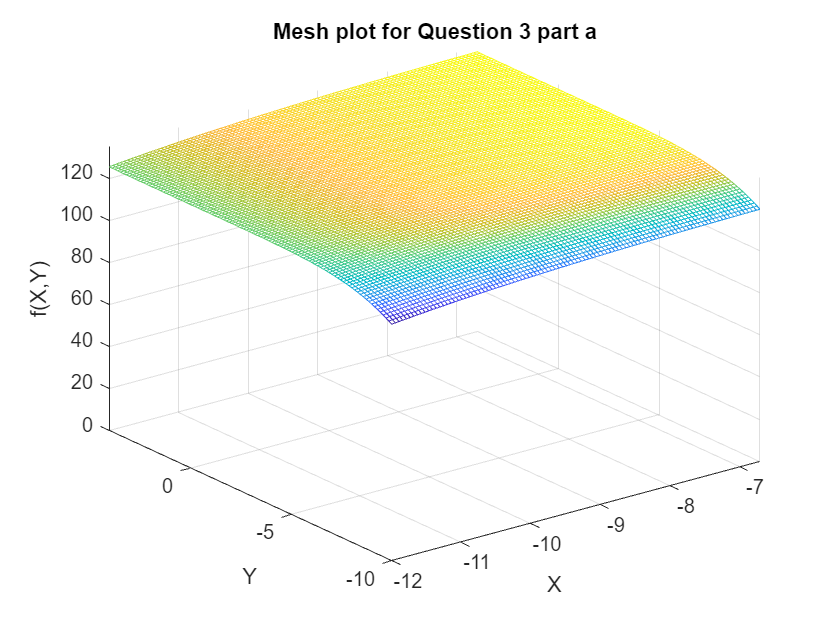

clf

x = linspace(a,b);
y = linspace(c,d);
[X,Y] = meshgrid(x,y);
Z = fQ3(X,Y);
mesh(X,Y,Z)

v = axis;
axis([a b c d 0 v(6)])

title('Mesh plot for Question 3 part a')
xlabel('X')
ylabel('Y')
zlabel('f(X,Y)')

**b) Integral estimate using Simpson's 3/8: Start with x axis**

nx = 3;
hx = (b-a)/nx;

ny = 3;
hy = (d-c)/ny;

iX0 = 3*hx/8*(fQ3(a,c)+3*fQ3(a+hx,c)+3*fQ3(a+2*hx,c)+fQ3(b,c));
iX1 = 3*hx/8*(fQ3(a,c+hy)+3*fQ3(a+hx,c+hy)+3*fQ3(a+2*hx,c+hy)+fQ3(b,c+hy));
iX2 = 3*hx/8*(fQ3(a,c+2*hy)+3*fQ3(a+hx,c+2*hy)+3*fQ3(a+2*hx,c+2*hy)+fQ3(b,c+2*hy));
iX3 = 3*hx/8*(fQ3(a,d)+3*fQ3(a+hx,d)+3*fQ3(a+2*hx,d)+fQ3(b,d));

integralSimp38IQ3Xaxis = 3*hy/8*(iX0+ 3*iX1 + 3*iX2 + iX3);

fprintf('Estemate of the value of the 2D integral staring with the x-axis: %.4f',integralSimp38IQ3Xaxis)

Estemate of the value of the 2D integral staring with the x-axis: 9528.6097

**c) Integral estimate using Simpson's 3/8: Start with y axis**

iY0 = 3*hx/8*(fQ3(a,c)+3*fQ3(a,c+hy)+3*fQ3(a,c+2*hy)+fQ3(a,d));
iY1 = 3*hx/8*(fQ3(a+hx,c)+3*fQ3(a+hx,c+hy)+3*fQ3(a+hx,c+2*hy)+fQ3(a+hx,d));
iY2 = 3*hx/8*(fQ3(a+2*hx,c)+3*fQ3(a+2*hx,c+hy)+3*fQ3(a+2*hx,c+2*hy)+fQ3(a+2*hx,d));
iY3 = 3*hx/8*(fQ3(b,c)+3*fQ3(b,c+hy)+3*fQ3(b,c+2*hy)+fQ3(b,d));

integralSimp38IQ3Yaxis = 3*hy/8*(iY0+ 3*iY1 + 3*iY2 + iY3);

fprintf('Estemate of the value of the 2D integral staring with the y-axis: %.4f',integralSimp38IQ3Yaxis)

Estemate of the value of the 2D integral staring with the y-axis: 9528.6097

**d) True value of the integral**

syms x y
ix = int(fQ3, x , a , b);
i_exact = double(int(ix , y , c , d));

fprintf('the true value of the integral is: %.4f',i_exact)

the true value of the integral is: 9549.2842

**e) Are the results from b through d the same? Why or why not?**

The results of the two types of integration estemation and the true value of the integral are not exactly the same. The values differ becuasethe matlab function that solves integrals 

uses a teqnique that symbolicaly solves the integral and then plugs the numbers in. The numerical methods way aproximates the values of the integrals useing cubic functions and so gives

slightly diferent values.

**f) Extra Credit - Plot a plane and extra points in a new figure**

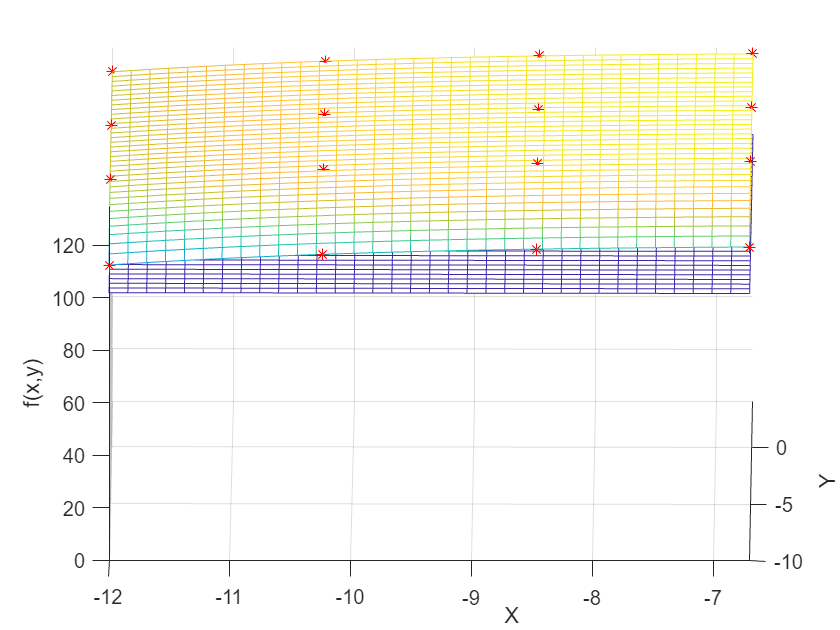

plane = @(x,y) x.*0+102;
fmesh(fQ3)
hold on;
fmesh(plane)
axis([a b c d 0 v(6)])
xlabel('X')
ylabel('Y')
zlabel('f(x,y)')
hold on;

plot3(a,c,fQ3(a,c),'r*',(a+hx),c,fQ3(a+hx,c),'r*',a+2*hx,c,fQ3(a+2*hx,c),'r*',b,c,fQ3(b,c),'r*',a,c+hy,fQ3(a,c+hy),'r*',a+hx,c+hy,fQ3(a+hx,c+hy),'r*',(a+2*hx),c+hy,fQ3(a+2*hx,c+hy),'r*',b,c+hy,fQ3(b,c+hy),'r*',a,c+2*hy,fQ3(a,c+2*hy),'r*',a+hx,c+2*hy,fQ3(a+hx,c+2*hy),'r*',a+2*hx,c+2*hy,fQ3(a+2*hx,c+2*hy),'r*',b,c+2*hy,fQ3(b,c+2*hy),'r*',a,d,fQ3(a,d),'r*',a+hx,d,fQ3(a+hx,d),'r*',a+2*hx,d,fQ3(a+2*hx,d),'r*',b,d,fQ3(b,d),'r*')
view(.3,24.2)

## Problem #4 - Gauss-Legendre

**SETUP FOR PROBLEM**

fQ4 = @(x) -0.5*x.^6 -0.5*x.^5 + 1.6*x.^4 + 1.8*x.^3 + 1.9*x.^2 - 0.9*x + 379;
a = -2;
b = 3;

**a) Plot the function. Include a solid black line on the x axis. **

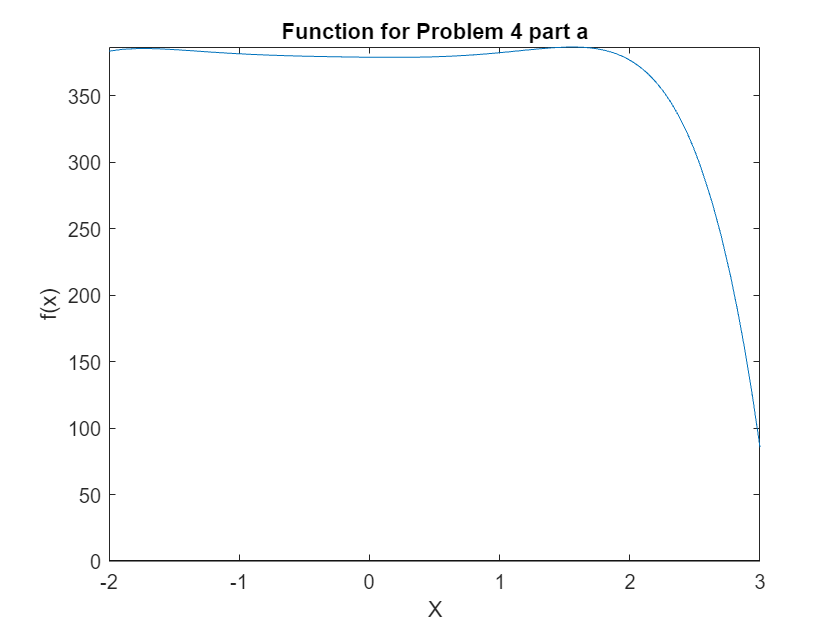

clf
xaxis = @(x) x.*0;
fplot(fQ4,[-2 3]);
hold on;
fplot(xaxis,[-2 3],'k')
 title('Function for Problem 4 part a')
 xlabel('X')
 ylabel('f(x)')

**b) Exact value of the integral**

syms x
integralfQ4Exact = int(fQ4,x,a,b);

fprintf('The exact value of the integral is %.10f',integralfQ4Exact)

The exact value of the integral is 1811.3928571429

**c) 3 Point Gauss-Legendre**

alpha1 = (a+b)/2;
alpha2 = (b-a)/2;

gaussLegendrefQ3 = @(xHat) fQ4(alpha1+alpha2*xHat)*alpha2;

c0 = 5/9;
c1 = 8/9;
c2 = c0;

x0 = -sqrt(3/5);
x1 = 0;
x2 = -1*x0;

integralfQ4GaussLegendre = c0*gaussLegendrefQ3(x0)+ c1*gaussLegendrefQ3(x1)+ c2*gaussLegendrefQ3(x2);
fprintf('The Gauss-Legendre estemated value of the integral is %.10f',integralfQ4GaussLegendre)

The Gauss-Legendre estemated value of the integral is 1825.3437500000

**d) Why is the true error nonzero for the Gauss-Legendre method?**

The gauss Legendre method can only perfectly estemate polynomails that do not have any truncation error. The three point gauss Legendre Method has a truncation error of about 

the sixth derivitive of the function. Because the function has a polynomial of degree equal to the derivitve the devivitive only can reach a constant value. this means that the error of integral is

gaurenteed to have some value.  

## Problem #5 - Romberg Integration

**SETUP FOR PROBLEM**

fQ5 = @(x) 10.*x.^5+2.2.*x.^4-0.1.*x.^3-0.8.*x.^2-6;
a = 1;
b = 4;

**a) Romberg by hand**

integral11 = trap(fQ5,a,b,1);
integral12 = trap(fQ5,a,b,2);
integral13 = trap(fQ5,a,b,4);
integral14 = trap(fQ5,a,b,8);
integral21 = 4/3*integral12-1/3*integral11;
integral22 = 4/3*integral13-1/3*integral12;
integral23 = 4/3*integral14-1/3*integral13;
integral31 = 16/15*integral22-1/15*integral21;
integral32 = 16/15*integral23-1/15*integral22;
integral41 = 64/63*integral32-1/63*integral31;
fprintf('j        k=1        k=2        k=3             k=4\n- ----------- ----------- ----------- ----------------\n1 %11.5f %11.5f %11.5f %16.10f\n2 %11.5f %11.5f %11.5f\n3 %11.5f %11.5f\n4 %11.5f',integral11,integral12,integral12,integral14,integral21,integral22,integral23,integral31,integral32,integral41)

j        k=1        k=2        k=3             k=4
- ----------- ----------- ----------- ----------------
1 16174.95000  9662.38125  9662.38125  7389.4954101563
2  7491.52500  7250.04375  7234.95117
3  7233.94500  7233.94500
4  7233.94500

**b) Romberg function**

[q,ea,iter] = romberg(fQ5,a,b);
fprintf('The textbook function integral estemation is: %.10f it took %d iterations',q,iter)

The textbook function integral estemation is: 7233.9450120884 it took 5 iterations

## Helper functions

### Hybrid simpsons's (n=7)

function [simp131338,simp381313,simp133813] = simpsons7(intFunction,lower,upper)
%this function uses the simpsons function

n = 7;
intSeg1 = 2;
intSeg2 = 3;
stepsize = (upper-lower)/n;

%first simpson 1/3 simpson 1/3 simpson 3/8

firstIncrement = lower + 2*stepsize;
secondIncrement = upper - 3*stepsize;

totalInt(1) = simpson13(intFunction,lower,firstIncrement,intSeg1);
totalInt(2) = simpson13(intFunction,firstIncrement,secondIncrement,intSeg1);
totalInt(3) = simpson38(intFunction,secondIncrement,upper,intSeg2);
simp131338 = sum(totalInt);

%second  simpson 3/8 simpson 1/3 simpson 1/3

firstIncrement = lower + 3*stepsize;
secondIncrement = upper - 2*stepsize;

totalInt(1) = simpson38(intFunction,lower,firstIncrement,intSeg2);
totalInt(2) = simpson13(intFunction,firstIncrement,secondIncrement,intSeg1);
totalInt(3) = simpson13(intFunction,secondIncrement,upper,intSeg1);
simp381313 = sum(totalInt);

%third simpson 1/3 simpson 3/8 simpson 1/3

firstIncrement = lower + 2*stepsize;
secondIncrement = upper - 2*stepsize;

totalInt(1) = simpson13(intFunction,lower,firstIncrement,intSeg1);
totalInt(2) = simpson38(intFunction,firstIncrement,secondIncrement,intSeg2);
totalInt(3) = simpson13(intFunction,secondIncrement,upper,intSeg1);
simp133813 = sum(totalInt);

end

### Romberg function (from textbook)

%textbook function modified
function [q,ea,iter] = romberg(func,a,b,es,maxit,varargin)

if nargin < 3
    error('at least 3 input required')
end

if nargin < 4 || isempty(es)
    es = 0.000001;
end

if nargin < 5 || isempty(maxit)
    maxit = 50;
end

n = 1;

I(1,1) = trap(func,a,b,varargin{:});
iter = 0;

while iter < maxit
    iter = iter + 1;
  
    n = 2^iter;

    I(iter+1,1) = trap(func,a,b,n,varargin{:});

    for k = 2:iter+1
        j = 2 + iter - k;
        I(j,k) = (4^(k-1)*I(j+1,k-1)-I(j,k-1))/(4^(k-1)-1);
    end

    ea = abs((I(1,iter+1)-I(2,iter))/I(1,iter+1))*100;

    if ea <= es
        break
    end

end
q = I(1,iter+1);
end

### MPRTE function

function out = mprte(true,estemate)
    out = abs(true-estemate)/true*100;
end